依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Reinforced final network：RSPd

[~,Score]=TransferLearning.UnifiedPcaModel(ZLayer=["RSPd2/3","RSPd5"],Paradigm="声光");

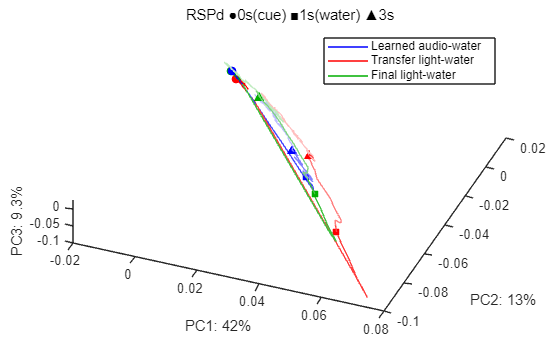

PCs=1:3;
LinesPC=table;
LinesPC.Points=permute(Score.Score{PCs,:,["Learned","Transfer","Final"]},[3,1,2]);
LinesPC.Color=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Markers=table;
Markers.Index=[24;32;48];
Markers.Shape=('os^')';
Fig=figure;
Lines=UniExp.SegmentFadePlot(LinesPC,Markers);
Explained=Score.Explained(PCs);
UniExp.PcAxLabels(table(PCs',Explained,'VariableNames',["Index","Explained"],'RowNames',["X";"Y";"Z"]));
L=legend(Lines,["Learned audio-water","Transfer light-water","Final light-water"],Location='northeast');
title('RSPd ●0s(cue) ■1s(water) ▲3s');
view(90*(1-Explained(1)/(Explained(1)+Explained(2))),90*(1-Explained(3)/sum(Explained)));
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('FinalRSPdPCA.png'),'-dpng','-r400');